clear all; clc;

## Covid data

Driver file to get you started with the covid dataset for project 2. 

set(groot, 'defaultaxesfontsize', 16); % , 'defaulttextinterpreter', 'latex'); 

T = readtable('covid.csv'); 

% convert the "continent" and "country" variables to the data type
% "categorical". This opens some opportunities, making it simpler to create
% selection vectors, but it makes some functions harder to use. 
T = convertvars(T, {'continent', 'country', 'iso_code'}, 'categorical'); 

% delete one day in 2019
T = T(T.date > '2019-12-31', :);

## Common sample selection

I = (T.new_cases >= 0) & (T.new_deaths >= 0) & (T.new_deaths < 100); 
T = T(I, :); 

% nice extra variable 
T.month = categorical(month(T.date));

%round new deaths to next integer to make poission feasible (will round to
%N = 0 decimals
T.rnd_new_deaths_per_million = round(T.new_deaths_per_million,0);


## Problem 2

2.1

% subplots
 
fig2 = figure('Name', 'subplots_add'); 

subplot(2, 3, 1)
hold on % this helps
% -------- Ecudaor ------
this_c = 'Ecuador';
outcome1 = 'rnd_new_deaths_per_million'; 
outcome2 = 'temperature';

I = T.country == this_c; 
%I = T.continent == this_c;
yyaxis left
plot(T.date(I),  T.(outcome1)(I)); ylabel('rounded new deaths per mio'); 
yyaxis right 
plot(T.date(I), T.(outcome2)(I)); %ylabel('temp'); 
%legend('New Deaths per million', 'Temperature'); 
title(this_c); 

subplot(2, 3, 2)
hold on % this helps


% -------- Denmark ------

this_c = 'Denmark';
outcome1 = 'rnd_new_deaths_per_million'; 
outcome2 = 'temperature';

I = T.country == this_c; 
%I = T.continent == this_c;
yyaxis left
plot(T.date(I),  T.(outcome1)(I)); %ylabel('new deaths per mio'); 
yyaxis right 
plot(T.date(I), T.(outcome2)(I)); %ylabel('temp'); 
%legend('New Deaths per million', 'Temperature'); 
title(this_c); 

% -------- South America ------

subplot(2, 3, 3)
hold on % this helps

this_c = 'South America';

outcome1 = 'rnd_new_deaths_per_million'; 
outcome2 = 'temperature';

C = T.continent == this_c; 

new_data = T(C,:);

A = new_data(:,[1 2 53 42] );
D = dummyvar(A.country);
B = table2timetable(A);
out = retime(B(:,[2:end]),'daily','mean');


%I = T.continent == this_c;
yyaxis left
plot(out.date,  out.(outcome1)); 
yyaxis right 
plot(out.date, out.(outcome2)); ylabel('temperature'); 
%legend('New Deaths per million', 'Temperature'); 
title(this_c); 



% -------- Europe ------

subplot(2, 3, 6)
hold on % this helps

this_c = 'Europe';

outcome1 = 'rnd_new_deaths_per_million'; 
outcome2 = 'temperature';

C = T.continent == this_c; 

new_data = T(C,:);

A = new_data(:,[1 2 53 42] )

A = 12606×4 table
    country       date       rnd_new_deaths_per_million    temperature
    _______    __________    __________________________    ___________

    Albania    2020-03-09                0                    10.6    
    Albania    2020-03-10                0                     9.4    
    Albania    2020-03-11                0                    10.2    
    Albania    2020-03-12                0                    11.9    
    Albania    2020-03-13                0                    12.7    
    Albania    2020-03-14                0                    13.2    
    Albania    2020-03-15                0                    11.8    
    Albania    2020-03-16                0                    10.7    
    Albania    2020-03-17                0                     9.5    
    Albania    2020-03-18                0                    12

B = table2timetable(A);
out = retime(B(:,[2:end]),'daily','mean');


%I = T.continent == this_c;
yyaxis left
plot(out.date,  out.(outcome1)); %ylabel('deaths per mio'); 
yyaxis right 
plot(out.date, out.(outcome2)); ylabel('temperature'); 
%legend('New Deaths per million', 'Temperature'); 
title(this_c); 



% -------- World ------

subplot(2, 3, [4 5])
hold on % this helps

A = T(:,[1 4 2 42 53] )

A = 48537×5 table
      country      continent       date       temperature    rnd_new_deaths_per_million
    ___________    _________    __________    ___________    __________________________

    Afghanistan      Asia       2020-01-01       5.5667                  0             
    Afghanistan      Asia       2020-01-02       4.1667                  0             
    Afghanistan      Asia       2020-01-03          4.8                  0             
    Afghanistan      Asia       2020-01-04          4.4                  0             
    Afghanistan      Asia       2020-01-05       4.0333                  0             
    Afghanistan      Asia       2020-01-06       2.6667                  0             
    Afghanistan      Asia       2020-01-07          0.2                  0             
    Afghanistan    

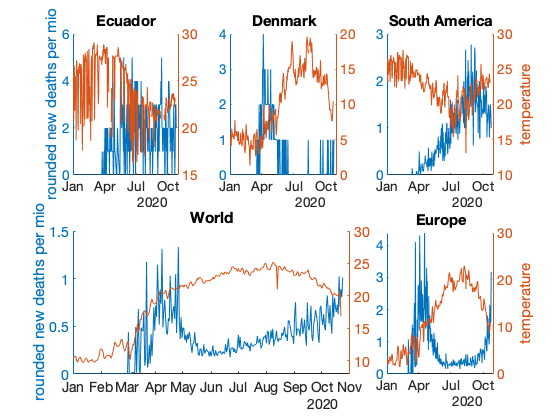

B = table2timetable(A);
out = retime(B(:,[3:end]),'daily','mean');


%I = T.continent == this_c;
yyaxis left
plot(out.date,  out.(outcome1)); ylabel('rounded new deaths per mio'); 
yyaxis right 
plot(out.date, out.(outcome2)); %ylabel(outcome2); 
%legend('New Deaths per million', 'Temperature'); 
title('World')

## WORLD ESTIMATION

global x y

temp_world = A.temperature;
death_world = A.rnd_new_deaths_per_million;

%n= 48537;

world = [death_world,temp_world]

world =          0    5.5667
         0    4.1667
         0    4.8000
         0    4.4000
         0    4.0333
         0    2.6667
         0    0.2000
         0    0.5667
         0    0.1000
         0    2.0000


world(any(isnan(world), 2), :) = [];
n = 34072

n = 34072

x_world = [ones(n,1), world(:,2)];
y_world = world(:,1);

k = numel(x_world(1,:));
% CREATE LABELS
lbly = {'DEATHS'};
lblx = {'CONSTANT'; 'TEMPERATURE'};

## OLS ESTIMATION

[b_ols,se_ols] = myols(y_world,x_world);

s2_ols = b_ols(end)^2;     % estimated error term variance
res = y_world-x_world*b_ols(1:k);    % predicted residuals
ybar = y_world-mean(y_world);        % demeaned observed outcome
R2_ols = 1-(res'*res)/(ybar'*ybar);   % R^2 coefficient of determination

% Print results
disp('OLS estimates');

OLS estimates


disp('================================================');

disp('             Param. est.  s.e.         t-value');

             Param. est.  s.e.         t-value


for r=1:length(lblx)
  fprintf('%-10s %11.4f %11.4f %11.4f\n', ...
          lblx{r,1}, [b_ols(r,1),se_ols(r,1),b_ols(r,1)./se_ols(r,1)]);
end

CONSTANT        0.4362      0.0133     32.7829
TEMPERATURE     -0.0046      0.0006     -7.8002


disp('------------------------------------------------');

------------------------------------------------


disp(['R-squared     ', num2str(R2_ols)]);

R-squared     0.0017826


disp(['Sigma         ', num2str(sqrt(s2_ols))]);

Sigma         0.0045673


disp('================================================');

% from: https://se.mathworks.com/matlabcentral/answers/241212-computing-mean-by-group-need-help-with-speed
%n = 200000;
%Xw = rand(n,20);
%id = ceil(rand(n,1) * 10);
%[,,c]=unique(id);
%[ii,jj] = ndgrid(c,1:size(Xw,2));
%bb = accumarray([ii(:),jj(:)], Xw(:), [], @mean);
%out = Xw - bb(c,:);

% create new df without nans with only temp and new deaths per mio
AVG = rmmissing(T(:,[1 53 42 ]));

% calculate mean_temp and mean_deaths per country
country_mean = varfun(@nanmean,AVG,'InputVariables','temperature','GroupingVariables','country')

country_mean = 151×3 table
      country      GroupCount    nanmean_temperature
    ___________    __________    ___________________

    Afghanistan       284              19.704       
    Albania           226              19.946       
    Algeria           289              22.303       
    Angola            213              23.892       
    Argentina         147               14.04       
    Armenia           285              9.7142       
    Australia         294              18.465       
    Austria           294              9.7119       
    Azerbaijan        287              16.642       
    Bahrain           293              29.093       
    Bangladesh        221              28.504       
    Belarus           286              10.948       
    Belgium           258              13.302       
    Belize            211              29.074       
    Benin             

%mean_i = @(i) table2array(mean(country_mean.country == i,3) );
country_mean_D = varfun(@nanmean,AVG,'InputVariables','rnd_new_deaths_per_million','GroupingVariables','country')

country_mean_D = 151×3 table
      country      GroupCount    nanmean_rnd_new_deaths_per_million
    ___________    __________    __________________________________

    Afghanistan       284                     0.091549             
    Albania           226                      0.64602             
    Algeria           289                     0.013841             
    Angola            213                            0             
    Argentina         147                      0.34694             
    Armenia           285                       1.2561             
    Australia         294                      0.07483             
    Austria           294                      0.30952             
    Azerbaijan        287                      0.15331             
    Bahrain           293                      0.66553             
    Bangladesh        221                           

country_mean_D = country_mean_D(:,"nanmean_rnd_new_deaths_per_million");
between_table = [country_mean,country_mean_D ];

% calculate de-meaned Y and X per observation
[C, ia, ic] = unique(AVG.country);
Xw = table2array(AVG(:,2:end));
[ii,jj] = ndgrid(ic,1:size(Xw,2));
bb = accumarray([ii(:),jj(:)], Xw(:), [], @mean);
out = Xw - bb(ic,:);
AVG.demeanedY = out(:,1);
AVG.demeanedX = out(:,2);

%create between arrays
n_between = size(between_table,1);
Y_between = table2array(between_table(:,"nanmean_rnd_new_deaths_per_million"));
X_between = [ones(n_between,1),table2array(between_table(:,"nanmean_temperature"))];

%create within arrays
n_within = size(AVG,1);
Y_within = table2array(AVG(:,"demeanedY"));
X_within = [table2array(AVG(:,"demeanedX"))];
%X_within = [ones(n_within,1),table2array(AVG(:,"demeanedX"))];

% -----------------------------

%BETWEEN OLS Y_hat auf X_hat
%define labels
lbly = {'DEATHS'};
lblx = {'CONSTANT';'TEMPERATURE'};

k = numel(X_between(1,:));
[b_between,se_between] = myols(Y_between,X_between);

s2_between = b_between(end)^2;     % estimated error term variance
res = Y_between-X_between*b_between(1:k);    % predicted residuals
ybar = Y_between-mean(Y_between);        % demeaned observed outcome
R2_between = 1-(res'*res)/(ybar'*ybar);   % R^2 coefficient of determination

% Print results
disp('Between OLS estimates');

Between OLS estimates


disp('================================================');

disp('             Param. est.  s.e.         t-value');

             Param. est.  s.e.         t-value


for r=1:length(lblx)
  fprintf('%-10s %11.4f %11.4f %11.4f\n', ...
          lblx{r,1}, [b_between(r,1),se_between(r,1),b_between(r,1)./se_between(r,1)]);
end

CONSTANT        0.6027      0.1132      5.3250
TEMPERATURE     -0.0129      0.0050     -2.5584


disp('------------------------------------------------');

------------------------------------------------


disp(['R-squared     ', num2str(R2_between)]);

R-squared     0.042079


disp(['Sigma         ', num2str(sqrt(s2_between))]);

Sigma         0.012908


disp('================================================');


% -----------------------------

%WITHIN OLS Y_demeaned auf X_demeaned
lbly = {'DEATHS'};
lblx = {'TEMPERATURE'};

k = numel(X_within(1,:));
[b_within,se_within] = myols(Y_within,X_within);

s2_within = b_within(end)^2;     % estimated error term variance
res = Y_within-X_within*b_within(1:k);    % predicted residuals
ybar = Y_within-mean(Y_within);        % demeaned observed outcome
R2_within = 1-(res'*res)/(ybar'*ybar);   % R^2 coefficient of determination

% Print results
disp('Within OLS estimates');

Within OLS estimates


disp('================================================');

disp('             Param. est.  s.e.         t-value');

             Param. est.  s.e.         t-value


for r=1:length(lblx)
  fprintf('%-10s %11.4f %11.4f %11.4f\n', ...
          lblx{r,1}, [b_within(r,1),se_within(r,1),b_within(r,1)./se_within(r,1)]);
end

TEMPERATURE      0.0145      0.0009     16.1928


disp('------------------------------------------------');

------------------------------------------------


disp(['R-squared     ', num2str(R2_within)]);

R-squared     0.0076371


disp(['Sigma         ', num2str(sqrt(s2_within))]);

Sigma         0.0145


disp('================================================');

## Denmark or Ecuador ESTIMATION

Default is on Denmark. For Ecuador change temp_col and death_col to "Ecuador" and comment n_denmark out but n_ecuador = 255 in. Remember to change the chosen n in x_col as well.

global x y
temp_col = A.temperature(A.country == "Denmark");
death_col = A.rnd_new_deaths_per_million(A.country == "Denmark");

col = [death_col,temp_col];
col(any(isnan(col), 2), :) = [];

%n_ecuador = 255;
n_denmark = 294

n_denmark = 294

x_col = [ones(n_denmark,1), col(:,2)];
y_col = col(:,1);

x_DK = x_col;
y_DK = y_col;

k = numel(x_col(1,:));
% CREATE LABELS
lbly = {'DEATH'};
lblx = {'CONSTANT'; 'TEMPERATURE'};

## OLS ESTIMATION

[b_ols,se_ols] = myols(y_col,x_col);

s2_ols = b_ols(end)^2;     % estimated error term variance
res = y_col-x_col*b_ols(1:k);    % predicted residuals
ybar = y_col-mean(y_col);        % demeaned observed outcome
R2_ols = 1-(res'*res)/(ybar'*ybar);   % R^2 coefficient of determination

% Print results
disp('OLS estimates');

OLS estimates


disp('================================================');

disp('             Param. est.  s.e.         t-value');

             Param. est.  s.e.         t-value


for r=1:length(lblx)
  fprintf('%-10s %11.4f %11.4f %11.4f\n', ...
          lblx{r,1}, [b_ols(r,1),se_ols(r,1),b_ols(r,1)./se_ols(r,1)]);
end

CONSTANT        0.8352      0.1045      7.9916
TEMPERATURE     -0.0435      0.0094     -4.6420


disp('------------------------------------------------');

------------------------------------------------


disp(['R-squared     ', num2str(R2_ols)]);

R-squared     0.068723


disp(['Sigma         ', num2str(sqrt(s2_ols))]);

Sigma         0.043452


disp('================================================');

## Continent estimation

this_c = "South America"

this_c = "South America"


global x y

temp_cont = A.temperature(A.continent == this_c);
death_cont = A.rnd_new_deaths_per_million(A.continent == this_c);

continent_data = [death_cont,temp_cont]

continent_data =          0   24.7417
         0   24.1278
         0   24.1611
         0   24.5268
         0   23.3319
         0   23.1528
         0   24.7278
         0   22.6875
         0   19.2386
         0   19.6268


continent_data(any(isnan(continent_data), 2), :) = [];

n = size(continent_data,1)

n = 2212


x_cont = [ones(n,1), continent_data(:,2)];
y_cont = continent_data(:,1);

k = numel(x_cont(1,:));
% CREATE LABELS
lbly = {'DEATHS'};
lblx = {'CONSTANT'; 'TEMPERATURE'};

## OLS ESTIMATION

[b_ols,se_ols] = myols(y_cont,x_cont);

s2_ols = b_ols(end)^2;     % estimated error term variance
res = y_cont-x_cont*b_ols(1:k);    % predicted residuals
ybar = y_cont-mean(y_cont);        % demeaned observed outcome
R2_ols = 1-(res'*res)/(ybar'*ybar);   % R^2 coefficient of determination

% Print results
disp('OLS estimates');

OLS estimates


disp('================================================');

disp('             Param. est.  s.e.         t-value');

             Param. est.  s.e.         t-value


for r=1:length(lblx)
  fprintf('%-10s %11.4f %11.4f %11.4f\n', ...
          lblx{r,1}, [b_ols(r,1),se_ols(r,1),b_ols(r,1)./se_ols(r,1)]);
end

CONSTANT        1.5555      0.1216     12.7937
TEMPERATURE     -0.0306      0.0053     -5.7563


disp('------------------------------------------------');

------------------------------------------------


disp(['R-squared     ', num2str(R2_ols)]);

R-squared     0.014772


disp(['Sigma         ', num2str(sqrt(s2_ols))]);

Sigma         0.030589


disp('================================================');

## SELECT SAMPLE


%**********************************************************************************************
% SELECT YOUR SAMPLE
%**********************************************************************************************

criterium = 1;
% 1 = Northern Hemispere  
% 0 = Southern Hemispere 
% 2 = Scandinavian countries
% 3 = southern european countries
% or
%4 for Jan - May
% or
% 5 for May - Okt
% or
% "Denmark"
% or
% "Europa"

%**********************************************************************************************
%*******************        Single continent         ******************************************
%**********************************************************************************************

%T_samp = T(T.continent == criterium,:)

%**********************************************************************************************
%*******************        Single country         ********************************************
%**********************************************************************************************

%T_samp = T(T.country == criterium,:)

%**********************************************************************************************
%*******************        Southern Europe          ********************************************
%**********************************************************************************************

%medit = zeros (size(T,1), 1);
%medit(T.country== 'Italy') = 3;
%medit(T.country== 'Spain') = 3;
%medit(T.country== 'Portugal') = 3;
%medit(T.country== 'Greece') = 3;
%medit(T.country== 'Malta') = 3;

%T_samp = addvars(T,medit)
%T_samp = T_samp(T_samp.medit == criterium,:)

%**********************************************************************************************
%*******************        Scandinavia             ********************************************
%**********************************************************************************************

%Scandi = zeros (size(T,1), 1);
%Scandi(T.country== 'Sweden') = 2;
%Scandi(T.country== 'Norway') = 2;
%Scandi(T.country== 'Denmark') = 2;
%Scandi(T.country== 'Iceland') = 2;
%Scandi(T.country== 'Finland') = 2;

%T_samp = addvars(T,Scandi)
%T_samp = T_samp(T_samp.Scandi == criterium,:)

%**********************************************************************************************
%*******************        World         *****************************************************
%**********************************************************************************************

%T_samp = T;

%T_samp(T_samp.country == "Russia", :) = [];
%T_samp(T_samp.country =="China", :) = [];
%T_samp(T_samp.country == "Turkey", :) = [];
%T_samp(T_samp.country == "Iran", :) = [];

%**********************************************************************************************
%*******************        hemisphere         ************************************************
%**********************************************************************************************

Hem = zeros (size(T,1), 1);
Hem(T.continent== 'Europe') = 1;
Hem(T.continent== 'North America') = 1;
Hem(T.continent== 'Asia') = 1;

T_samp = addvars(T,Hem)

T_samp = 48537×54 table
      country         date       iso_code    continent    total_cases    new_cases    new_cases_smoothed    total_deaths    new_deaths    new_deaths_smoothed    total_cases_per_million    new_cases_per_million    new_cases_smoothed_per_million    total_deaths_per_million    new_deaths_per_million    new_deaths_smoothed_per_million    total_tests    new_tests    total_tests_per_thousand    new_tests_per_thousand    new_tests_smoothed    new_tests_smoothed_per_thousand    tests_per_case    positive_rate    tests_units    stringency_index</

T_samp = T_samp(T_samp.Hem == criterium,:)

T_samp = 32073×54 table
      country         date       iso_code    continent    total_cases    new_cases    new_cases_smoothed    total_deaths    new_deaths    new_deaths_smoothed    total_cases_per_million    new_cases_per_million    new_cases_smoothed_per_million    total_deaths_per_million    new_deaths_per_million    new_deaths_smoothed_per_million    total_tests    new_tests    total_tests_per_thousand    new_tests_per_thousand    new_tests_smoothed    new_tests_smoothed_per_thousand    tests_per_case    positive_rate    tests_units    stringency_index</



T_samp(T_samp.country == "Russia", :) = [];
T_samp(T_samp.country =="China", :) = [];
T_samp(T_samp.country == "Turkey", :) = [];
T_samp(T_samp.country == "Iran", :) = [];


%**********************************************************************************************
%*******************        1st vs. 2nd         ************************************************
%**********************************************************************************************
%half = zeros (size(T,1), 1);
%half(T.month == "1") = 4;
%half(T.month == "2") = 4;
%half(T.month =="3") = 4;
%half(T.month == "4") = 4;
%half(T.month == "5") = 4;
%half(T.month == "6") = 5;
%half(T.month == "7") = 5;
%half(T.month =="8")= 5;
%half(T.month == "9") = 5;
%half(T.month == "10") = 5;

%T_samp = addvars(T,half)
%T_samp = T_samp(T_samp.half == criterium,:)

%T_samp(T_samp.country == "Russia", :) = [];
%T_samp(T_samp.country =="China", :) = [];
%T_samp(T_samp.country == "Turkey", :) = [];
%T_samp(T_samp.country == "Iran", :) = [];


% *****************************************
data =  T_samp(:,[ 53 26 28 29 32 34 35 36 37 39 40 41 42 ]);
k = width(data)-1;

data = table2array(data);
data(any(isnan(data), 2), :) = [];

% only extract DK data
%DK_fit =  T_samp(7790:8083,[53 26 28 29 32 34 35 36 37 39 40 41 42 ]);
%DK_fit = DK_fit(1:294,:);
%DK_fit(226) = [];
%DK_fit = table2array(DK_fit);
%DK_fit(any(isnan(DK_fit), 2), :) = [];

% Extract variables
n = size(data,1);
new_deaths_per_mio  = data(:,1);
stringency = data(:,2);
density    = data(:,3);
medianage  = data(:,4);
gpdpc      = data(:,5);
cardiovasc  = data(:,6);
diabetes  = data(:,7);
fem_smoker  = data(:,8);
male_smoker     = data(:,9);
beds_per_th     = data(:,10);
life_exp = data(:,11);
hdi     = data(:,12);
temperature     = data(:,13);
constant =  ones(n,1);
%constant = array2table(constant) ;

y = new_deaths_per_mio;
x = [constant, temperature, stringency, density, medianage, gpdpc, cardiovasc, diabetes, fem_smoker, male_smoker, beds_per_th, life_exp, hdi];
k = numel(x(1,:));

y_distrgraph = y;
x_distrgraph = x;

% CREATE LABELS
lbly = {'New Deaths per mio'};
lblx = {'CONSTANT'; 'Temperature'; 'Stringency'; 'Density';'Median Age'; 'GDP pc'; 'Cardiovascular death rate';'Diabetes'; 'Female smokerr'; 'Male Smoker'; 'Hospital bed per thousand';'Life expectancy'; 'HDI'};


%**********************************************************************************************
% TOBIT
%**********************************************************************************************

% ----------------------------------------------------------------
% Optimizer settings
opt = optimoptions(@fminunc,...
    'Display','iter',...                 % 'iter' (for every iteration), 'final' or 'off'.
    'Algorithm','quasi-newton',...       % Alternatively, we can use 'trust-region'
    'StepTolerance',1e-08,...            % Optimizer will terminate if the norm of (thetaNew - thetaOld) is smaller than this
    'FiniteDifferenceType','central',... % These are more precise than 'forward', but require twice as many computations
    'MaxFunEvals',10000,...
    'HessUpdate','bfgs'...               % 'iter' (for every iteration), 'final' or 'off'.
    );

opt_search =  optimset('Display','iter',...
    'TolX',1e-08,...
    'TolFun',1e-08,...
    'MaxIter',20000,...
    'MaxFunEvals',50000,'HessUpdate','bfgs');

% ----------------------------------------------------------------
% Estimation
theta0 = tobit.starting_values(y,x);      % starting values
q = @(theta) tobit.criterion(y,x,theta);  % criterion function
[thetahat,se_thetahat, cov] = estimation_search.estimate_m(q,theta0,numel(y),opt_search,'Outer Product');

 
 Iteration   Func-count     min f(x)         Procedure
     0            1          33108.6         
     1           15          31221.2         initial simplex
     2           17            24523         expand
     3           18            24523         reflect
     4           19            24523         reflect
     5           20            24523         reflect
     6           21            24523         reflect
     7           22            24523         reflect
     8           23            24523         reflect
     9           24            24523         reflect
    10           25            24523         reflect
    11           26            24523         reflect
    12           27            24523         reflect
    13           28            24523         reflect
    14           29            24523         reflect
    15           30            24523         reflect
    16           31            24523         reflect
    17           32            24523      

thetahat =   -16.3594
    0.0438
    0.0219
   -0.0003
    0.1558
   -0.0000
    0.0030
    0.0694
   -0.0536
   -0.0301


fval = 1.4589e+04

exitflag = 1

output = struct with fields:
    iterations: 7652
     funcCount: 10264
     algorithm: 'Nelder-Mead simplex direct search'
       message: 'Optimization terminated:↵ the current x satisfies the termination criteria using OPTIONS.TolX of 1.000000e-08 ↵ and F(X) satisfies the convergence criteria using OPTIONS.TolFun of 1.000000e-08 ↵'


theta_1: -16.3594  (se = 1.5747, t = -10.39)
theta_2:   0.0438  (se = 0.0055, t =  7.97)
theta_3:   0.0219  (se = 0.0016, t = 13.61)
theta_4:  -0.0003  (se = 0.0001, t = -4.38)
theta_5:   0.1558  (se = 0.0101, t = 15.38)
theta_6:  -0.0000  (se = 0.0000, t = -7.67)
theta_7:   0.0030  (se = 0.0005, t =  5.95)
theta_8:   0.0694  (se = 0.0131, t =  5.30)
theta_9:  -0.0536  (se = 0.0047, t = -11.51)
theta_10:  -0.0301  (se = 0.0041, t = -7.32)
theta_11:   0.0265  (se = 0.0195, t =  1.36)
theta_12:   0.0137  (se = 0.0250, t =  0.55)
theta_13:   7.4703  (se = 1.1033, t =  6.77)
theta_14:   2.8931  (se = 0.0322, t = 89.86)


%[thetahat,se_thetahat] = estimation.estimate_m(q,theta0,numel(y),opt,'Outer Product');

estimation_search.print_results(thetahat,se_thetahat);

theta_1: -16.3594  (se = 1.5747, t = -10.39)
theta_2:   0.0438  (se = 0.0055, t =  7.97)
theta_3:   0.0219  (se = 0.0016, t = 13.61)
theta_4:  -0.0003  (se = 0.0001, t = -4.38)
theta_5:   0.1558  (se = 0.0101, t = 15.38)
theta_6:  -0.0000  (se = 0.0000, t = -7.67)
theta_7:   0.0030  (se = 0.0005, t =  5.95)
theta_8:   0.0694  (se = 0.0131, t =  5.30)
theta_9:  -0.0536  (se = 0.0047, t = -11.51)
theta_10:  -0.0301  (se = 0.0041, t = -7.32)
theta_11:   0.0265  (se = 0.0195, t =  1.36)
theta_12:   0.0137  (se = 0.0250, t =  0.55)
theta_13:   7.4703  (se = 1.1033, t =  6.77)
theta_14:   2.8931  (se = 0.0322, t = 89.86)



% Compute R^2
sigma_tobit = thetahat(k+1);
b_tobit = thetahat(1:k);
bse_tobit = se_thetahat(1:k);
xb_tobit = x*b_tobit;
yhat_tobit = xb_tobit.*normcdf(xb_tobit/sigma_tobit) + sigma_tobit*normpdf(xb_tobit/sigma_tobit);
rho = corr(y,yhat_tobit);
R2_tobit = rho^2;
res_tobit = y - xb_tobit;

% Print results
disp('');
disp('Tobit estimates');

Tobit estimates


disp('================================================');

disp('           Param. est.         s.e     t-value');

           Param. est.         s.e     t-value


for r=1:length(lblx)
  fprintf('%-10s %11.4f %11.4f %11.4f\n', ...
          lblx{r,1}, [b_tobit(r,1),bse_tobit(r,1),b_tobit(r,1)./bse_tobit(r,1)]);
end

CONSTANT      -16.3594      1.5747    -10.3890
Temperature      0.0438      0.0055      7.9698
Stringency      0.0219      0.0016     13.6133
Density        -0.0003      0.0001     -4.3778
Median Age      0.1558      0.0101     15.3810
GDP pc         -0.0000      0.0000     -7.6721
Cardiovascular death rate      0.0030      0.0005      5.9485
Diabetes        0.0694      0.0131      5.2982
Female smokerr     -0.0536      0.0047    -11.5089
Male Smoker     -0.0301      0.0041     -7.3222
Hospital bed per thousand      0.0265      0.0195      1.3624
Life expectancy      0.0137      0.0250      0.5470
HDI             7.4703      1.1033      6.7711


disp('------------------------------------------------');

------------------------------------------------


disp(['R-squared     ', num2str(R2_tobit)]);

R-squared     0.021009


disp(['Sigma         ', num2str(sigma_tobit)]);

Sigma         2.8931


disp('================================================');


% Marginal effects computed for the mean individual (x0)
x0    = mean(x,1);
xb    = x0*b_tobit;

% dE(y|x,y>0)/dx, see eq.(7)
phi         = normcdf(xb/sigma_tobit);
lambda     = normpdf(xb/sigma_tobit)/phi;    % inverse Mills ratio
correction = (1-lambda*((xb/sigma_tobit)+lambda));
margeff_mean_1 = b_tobit*correction;

% dE(y|x)/dx, see eq.(9)
margeff_mean_2 = b_tobit*phi;

%%%%%%%  Delta method standart errors for ME    %%%%%%%%
variance_tobit = bse_tobit.^2

variance_tobit =     2.4796
    0.0000
    0.0000
    0.0000
    0.0001
    0.0000
    0.0000
    0.0002
    0.0000
    0.0000



% unconditional case
d_lambda = (-lambda*(xb/sigma_tobit + lambda));
delta_h_uncond = (phi + b_tobit*normpdf(xb/sigma_tobit)*(x0/sigma_tobit));

%select 2nd row showing how ME of temp changes if x_k changes
delta_h_uncond = delta_h_uncond(2,:);
delta_h_uncond = delta_h_uncond'.^2;
cov_ME_uncond = delta_h_uncond.*variance_tobit;
se_ME_uncond = sqrt(cov_ME_uncond);

% conditional case
delta_h_cond = (1 - (2*b_tobit*lambda*(x0/sigma_tobit)+(b_tobit.^2)*(x0/sigma_tobit)*d_lambda - (lambda.^2+ b_tobit*(2*lambda - d_lambda))));
delta_h_cond = delta_h_cond(2,:);
delta_h_cond = delta_h_cond'.^2;
cov_ME_cond = delta_h_cond.*variance_tobit;
se_ME_cond = sqrt(cov_ME_cond);
    
% Pr(0|x,z)
Pr_tobit=1-phi;

% Print results
disp('');
disp('Marginal effect of an additional unit of temperature from tobit model');

Marginal effect of an additional unit of temperature from tobit model


disp(['dE(y|x,y>0)/dx         ', num2str(margeff_mean_1(2))]);

dE(y|x,y>0)/dx         0.0094129


disp(['SE cond.         ', num2str(sqrt(cov_ME_cond(2,:)))]);

SE cond.         0.013149


disp(['dE(y|x)/dx             ', num2str(margeff_mean_2(2))]);

dE(y|x)/dx             0.0084073


disp(['SE uncond.         ', num2str(sqrt(cov_ME_uncond(2,:)))]);

SE uncond.         0.0014771


disp(['Pr(y=0|x)             ', num2str(Pr_tobit)]);

Pr(y=0|x)             0.80807



%

## Poisson Regression

% POISSON REGRESSION
theta0 = poisson.starting_values(y,x);      % starting values
q = @(theta) poisson.criterion(y,x,theta);  % criterion function
%[thetahat,se_thetahat] = estimation.estimate_m(q,theta0,numel(y),opt,'Sandwich');
[thetahat,se_thetahat, cov_poss] = estimation_search_poss.estimate_m(q,theta0,numel(y),opt_search,'Hessian');

 
 Iteration   Func-count     min f(x)         Procedure
     0            1           151867         
     1           15           124804         initial simplex
     2           17          56700.5         expand
     3           18          56700.5         reflect
     4           19          56700.5         reflect
     5           20          56700.5         reflect
     6           21          56700.5         reflect
     7           22          56700.5         reflect
     8           23          56700.5         reflect
     9           24          56700.5         reflect
    10           25          56700.5         reflect
    11           26          56700.5         reflect
    12           27          56700.5         reflect
    13           28          56700.5         reflect
    14           29          56700.5         reflect
    15           30          56700.5         reflect
    16           31          56700.5         reflect
    17           32          56700.5      

thetahat =     4.5459
   -0.0048
    0.0252
   -0.0001
    0.0274
   -0.0000
   -0.0023
   -0.0307
   -0.0010
   -0.0280


fval = 1.1811e+04

exitflag = 1

output = struct with fields:
    iterations: 5769
     funcCount: 7838
     algorithm: 'Nelder-Mead simplex direct search'
       message: 'Optimization terminated:↵ the current x satisfies the termination criteria using OPTIONS.TolX of 1.000000e-08 ↵ and F(X) satisfies the convergence criteria using OPTIONS.TolFun of 1.000000e-08 ↵'


%[thetahat,se_thetahat] = estimation.estimate_m(q,thetahat,numel(y),opt,'Sandwich');

%estimation_search.print_results(thetahat,se_thetahat);

% Compute R^2
sigma_poisson = thetahat(k+1);
b_poisson = thetahat(1:k);
bse_poisson = se_thetahat(1:k);
xb_Poisson = x*b_poisson;
yhat_Poisson = exp(x*b_poisson);

Lam=exp(xb_Poisson);
L = mean(Lam),

L = 0.3699


ybar = mean(y);
R2_Poisson = sum((yhat_Poisson-ybar).^2) / sum((y-ybar).^2);


% Print results
disp('');
disp('Poisson estimates');

Poisson estimates


disp('================================================');

disp('           Param. est.         s.e     t-value');

           Param. est.         s.e     t-value


for r=1:length(lblx)
  fprintf('%-10s %11.4f %11.4f %11.4f\n', ...
          lblx{r,1}, [b_poisson(r,1),bse_poisson(r,1),b_poisson(r,1)./bse_poisson(r,1)]);
end

CONSTANT        4.5459      0.2828     16.0724
Temperature     -0.0048      0.0019     -2.5567
Stringency      0.0252      0.0006     44.0469
Density        -0.0001      0.0000     -6.7748
Median Age      0.0274      0.0041      6.6596
GDP pc         -0.0000      0.0000     -1.7662
Cardiovascular death rate     -0.0023      0.0002    -14.5087
Diabetes       -0.0307      0.0048     -6.3437
Female smokerr     -0.0010      0.0020     -0.4696
Male Smoker     -0.0280      0.0016    -17.3394
Hospital bed per thousand      0.0355      0.0078      4.5637
Life expectancy     -0.1259      0.0006   -220.6932
HDI             4.2742      0.3255     13.1327


disp('------------------------------------------------');

------------------------------------------------


disp(['R-squared     ', num2str(R2_Poisson)]);

R-squared     0.077379


disp(['Sigma         ', num2str(sigma_poisson)]);

Sigma         23.4583


disp('================================================');


% Marginal effects computed for the mean individual (x0)
x0    = mean(x,1);
xb    = x0*b_poisson;
mu=mean(yhat_Poisson)

mu = 0.3699


% dE(y|x)/dx, see eq.(9)
margeff_mean_2 = b_poisson*exp(xb);

% Delta method standart errors for ME
variance_poss = bse_poisson.^2;
delta_h_poss = (b_poisson*exp(xb)*x0 + exp(xb));
delta_h_poss = delta_h_poss(2,:);
delta_h_poss = delta_h_poss'.^2;
cov_ME_poss = delta_h_poss.*variance_poss;
se_ME_poss = sqrt(cov_ME_poss);

%
Pr_pois=exp(-mu);

% Print results
disp('');
disp('Marginal effect of an additional unit of temperature from Poisson model');

Marginal effect of an additional unit of temperature from Poisson model


%disp(['dE(y|x,y>0)/dx         ', num2str(margeff_mean_2(2))]);
disp(['dE(y|x)/dx             ', num2str(margeff_mean_2(2))]);

dE(y|x)/dx             -0.0013581


disp(['SE ME         ', num2str(se_ME_poss(2,:))]);

SE ME         0.00048375


disp(['Pr(y=0|x)             ', num2str(Pr_pois)]);

Pr(y=0|x)             0.69082


## 2.3

% At the bottom the bottom ... in case of errors run graphocs code in
% Command Window

%Probability of y = 0 in data
denom = size(y,1),

denom = 18037

idx=y==0;
nom=sum(idx(:));
Pr_ybigger0_data = nom/denom

Pr_ybigger0_data = 0.7859


%%%%%%%%%%%%%%% GRAPHS %%%%%%%%%%%%%%

% POSSION MODEL - SCATTER OF PREDICTED VALUES
% actualfunc_poiss = polyfit(xb_Poisson, y_distrgraph, 4);
% xFit_poiss = linspace(-6, 0.5, 200);
% yFit_poiss = polyval(actualfunc_poiss, xFit_poiss);

figure(11)
f11=scatter(xb_Poisson,y_distrgraph);
xlabel('xb');
ylabel('Rounded deaths per mio');
hold on;
scatter(xb_Poisson, yhat_Poisson,14,'filled');
hold on;
%plot(xFit_poiss,yFit_poiss, 'c-', 'LineWidth', 1);
lgd = legend('observed values','fitted values','Location',"northwest")

lgd =   Legend (observed values, fitted values) with properties:

         String: {'observed values'  'fitted values'}
       Location: 'northwest'
    Orientation: 'vertical'
       FontSize: 14.4000
       Position: [0.1446 0.8107 0.2625 0.0964]
          Units: 'normalized'

  Show all properties


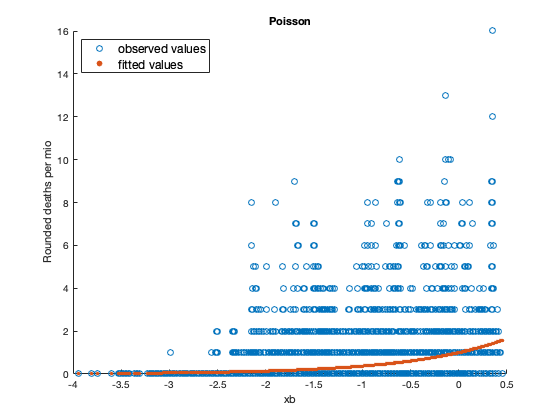

lgd.FontSize = 12;
title("Poisson");
%xlim([-25 10])
%ylim([0 120]);
hold off;

% TOBIT MODEL - SCATTER OF PREDICTED VALUES

% actualfunc_tobit = polyfit(xb_tobit, y_distrgraph, 4);
% xFit_tobit = linspace(-3.6, 1.5, 200);
% yFit_tobit = polyval(actualfunc_tobit, xFit_tobit);
%plot(xFit_tobit, yFit_tobit, 'b-', 'LineWidth', 2);

figure(12)
scatter(xb_tobit,y_distrgraph,40);
xlabel('xb');
ylabel('Rounded deaths per mio');
hold on;
scatter(xb_tobit, yhat_tobit,14,'filled');
hold on;
%plot(xFit_tobit,yFit_tobit, 'c-', 'LineWidth', 1);
lgd = legend('observed values','fitted values','Location',"northwest")

lgd =   Legend (observed values, fitted values) with properties:

         String: {'observed values'  'fitted values'}
       Location: 'northwest'
    Orientation: 'vertical'
       FontSize: 14.4000
       Position: [0.1446 0.8107 0.2625 0.0964]
          Units: 'normalized'

  Show all properties


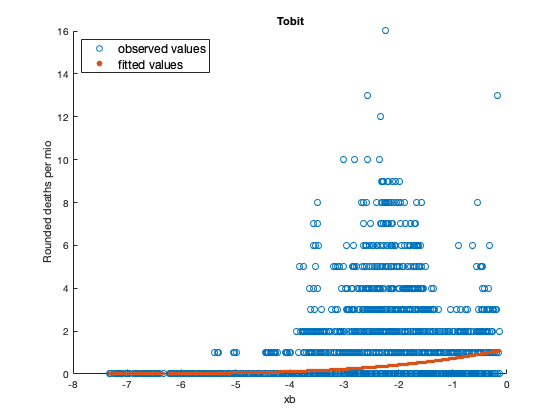

lgd.FontSize = 12;
title("Tobit");
hold off;

% POISSON MODEL - DISTRIBUTION OF ACTUAL VALUES
flaws = [0:70];
POISS = poisspdf(flaws,L);

figure(13)
%[f,xi] = ksdensity(y_distrgraph,'Bandwidth',0.45);
% small bandwidth far off
%plot(xi,f,'-r','LineWidth',2);
xlim([0 5])
%ylim([0 0.5]);
hold on
%[f,xi] = ksdensity(yhat_Poisson,'Bandwidth',1);
[f,xi] = ksdensity(y,'Bandwidth',1);
plot(xi,f,'--r','LineWidth',2);
hold on
grid on
line(flaws,POISS, 'LineWidth',2)
%scatter(flaws,POISS,'filled','b');
%line(flaws,POISS, 'LineWidth',2)
lgd1 = legend('kernel density actual deaths per mio. (bw 0.1)','Poisson Distr.','Location','northeast')

lgd1 =   Legend (kernel density actual deaths per mio. (bw 0.1), Poisson Distr.) with properties:

         String: {'kernel density actual deaths per mio. (bw 0.1)'  'Poisson Distr.'}
       Location: 'northeast'
    Orientation: 'vertical'
       FontSize: 14.4000
       Position: [0.2964 0.8107 0.5946 0.0964]
          Units: 'normalized'

  Show all properties


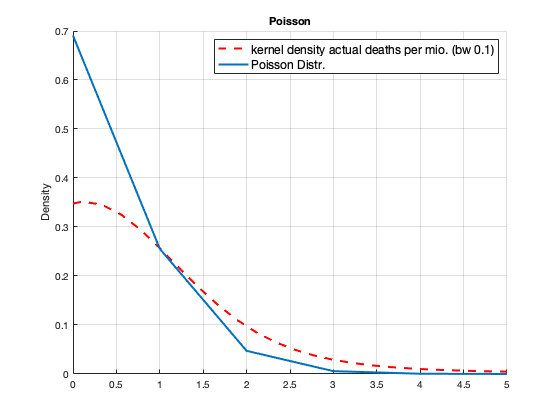

lgd1.FontSize = 12;
%set(lgd1,'color','none');
title("Poisson");
hold on
%[f,xi] = ksdensity(y_distrgraph,'Bandwidth',0.2);
%plot(xi,f,'-c','LineWidth',1);
ylabel('Density');
%xlabel('');
hold off

% TOBIT MODEL - DISTRIBUTION OF RESIDUALS

figure(14)

z = [-30:.1:30];
NORM = normpdf(z,0,1);

plot(z,NORM);
grid on
hold on
[f,xi] = ksdensity(res_tobit,'Bandwidth',0.01);
plot(xi,f,'--b','LineWidth',2);
lgd7 = legend('Std. Normal N(0,1)','kernel density tobit residuals (bw 0.1)','Location','northeast')

lgd7 =   Legend (Std. Normal N(0,1), kernel density tobit residuals (bw 0.1)) with properties:

         String: {'Std. Normal N(0,1)'  'kernel density tobit residuals (bw 0.1)'}
       Location: 'northeast'
    Orientation: 'vertical'
       FontSize: 14.4000
       Position: [0.3911 0.8107 0.5000 0.0964]
          Units: 'normalized'

  Show all properties


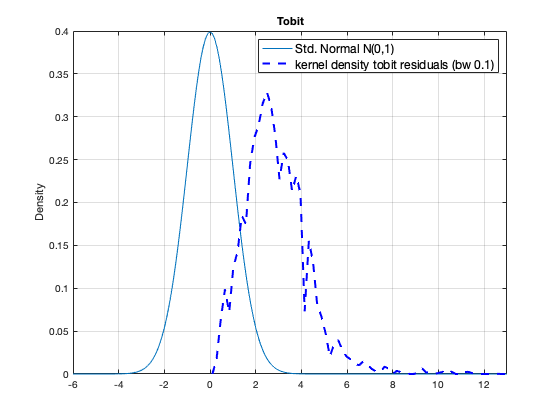

lgd7.FontSize = 12;
xlim([-6 13]);
% ylim([0 0.5]);
ylabel('Density');
%xlabel('');
title("Tobit");
hold off


% Jarque-Bera Test
[h,jbstat,p] = jbtest(res_tobit,[],0.01)

h = 1

jbstat = 0

p = 2.1628e+04

% Generate estimates for Denmark with b_tobit and b_poiss
criterium = "Denmark"

criterium = "Denmark"

T_samp = T(T.country == criterium,:)

T_samp = 298×53 table
    country       date       iso_code    continent    total_cases    new_cases    new_cases_smoothed    total_deaths    new_deaths    new_deaths_smoothed    total_cases_per_million    new_cases_per_million    new_cases_smoothed_per_million    total_deaths_per_million    new_deaths_per_million    new_deaths_smoothed_per_million    total_tests    new_tests    total_tests_per_thousand    new_tests_per_thousand    new_tests_smoothed    new_tests_smoothed_per_thousand    tests_per_case    positive_rate    tests_units    stringency_index

data =  T_samp(:,[53 26 28 29 32 34 35 36 37 39 40 41 42 ]);
data = table2array(data) ;
data(any(isnan(data), 2), :) = [];
% Extract variables
n = size(data,1);
new_deaths_per_mio  = data(:,1);
stringency = data(:,2);
density    = data(:,3);
medianage  = data(:,4);
gpdpc      = data(:,5);
cardiovasc  = data(:,6);
diabetes  = data(:,7);
fem_smoker  = data(:,8);
male_smoker     = data(:,9);
beds_per_th     = data(:,10);
life_exp = data(:,11);
hdi     = data(:,12);
temperature     = data(:,13);
constant =  ones(n,1);
%const = array2table(constant) ;
y_DK = new_deaths_per_mio;
x_DK = [constant, temperature, stringency, density, medianage, gpdpc, cardiovasc, diabetes, fem_smoker, male_smoker, beds_per_th, life_exp, hdi];
k = numel(x(1,:));
y_distrgraph = y;
% CREATE LABELS
lbly = {'New Deaths per mio'};
lblx = {'CONSTANT'; 'Temperature'; 'Stringency'; 'Density'; 'Median Age'; 'GDP pc'; 'Cardiovascular death rate';'Diabetes'; 'Female smokerr'; 'Male Smoker'; 'Hospital bed per thousand';'Life expectancy'; 'HDI'};


yhat_Poisson_DK = yhat_Poisson(4054:4346);
xb_DK = x_DK*b_poisson

xb_DK =    -1.5487
   -1.5422
   -1.5408
   -1.5391
   -1.5434
   -1.5512
   -1.5485
   -1.5474
   -1.5455
   -1.5475



scatter(xb_DK,y_DK);
hold on
scatter(xb_DK,yhat_Poisson_DK,20);
title("Poisson");
%xlim([-0.5 5]);
ylabel('Rounded New Deaths per mio.');
%xlabel('');
lgd7 = legend('observations DK','Predictions','Location','northwest')

lgd7 =   Legend (observations DK, Predictions) with properties:

         String: {'observations DK'  'Predictions'}
       Location: 'northwest'
    Orientation: 'vertical'
       FontSize: 14.4000
       Position: [0.1446 0.8107 0.2643 0.0964]
          Units: 'normalized'

  Show all properties


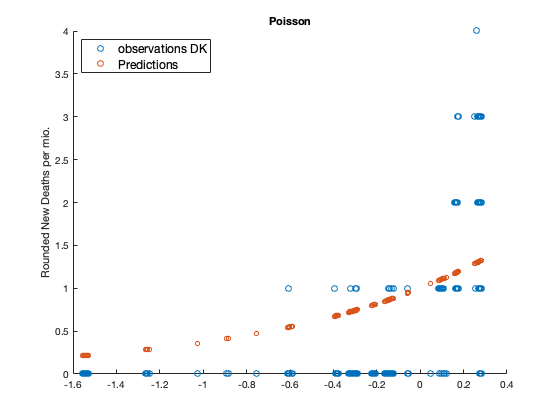

lgd7.FontSize = 12;
hold off

yhat_tobit_DK = yhat_tobit(4054:4346);

xb_DK = x_DK*b_tobit;
scatter(xb_DK,y_DK,60);
hold on
scatter(xb_DK,yhat_tobit_DK,5);
title("Tobit");
xlim([-4 0]);
ylabel('Rounded New Deaths per mio.');
%xlabel('');
lgd7 = legend('observations DK','Predictions','Location','northwest')

lgd7 =   Legend (observations DK, Predictions) with properties:

         String: {'observations DK'  'Predictions'}
       Location: 'northwest'
    Orientation: 'vertical'
       FontSize: 14.4000
       Position: [0.1446 0.8107 0.2643 0.0964]
          Units: 'normalized'

  Show all properties


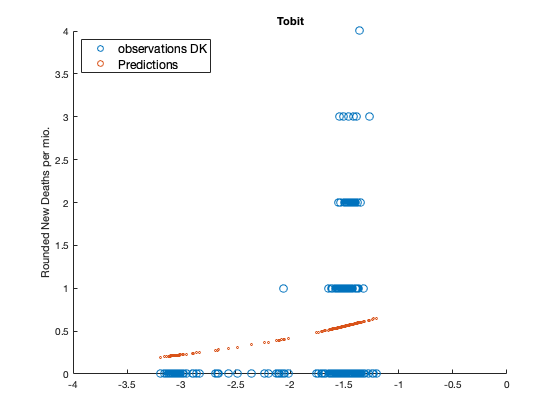

lgd7.FontSize = 12;
hold off

## 2.4

## TOBIT (logistic)

% Estimation
theta0 = tobit_1_logistic.starting_values(y,x);      % starting values
q = @(theta) tobit_1_logistic.criterion(y,x,theta);  % criterion function
[thetahat,se_thetahat] = estimation_search.estimate_m(q,theta0,numel(y),opt_search,'Outer Product');

 
 Iteration   Func-count     min f(x)         Procedure
     0            1            26802         
     1           15          25885.4         initial simplex
     2           17          22428.1         expand
     3           18          22428.1         reflect
     4           19          22428.1         reflect
     5           20          22428.1         reflect
     6           21          22428.1         reflect
     7           22          22428.1         reflect
     8           23          22428.1         reflect
     9           24          22428.1         reflect
    10           25          22428.1         reflect
    11           26          22428.1         reflect
    12           27          22428.1         reflect
    13           28          22428.1         reflect
    14           29          22428.1         reflect
    15           30          22428.1         reflect
    16           31          22428.1         reflect
    17           32          22428.1      

thetahat =   -10.8342
    0.0457
    0.0306
   -0.0003
   -0.1161
   -0.0000
    0.0016
    0.0684
    0.0726
   -0.0428


fval = 1.4313e+04

exitflag = 1

output = struct with fields:
    iterations: 6403
     funcCount: 8716
     algorithm: 'Nelder-Mead simplex direct search'
       message: 'Optimization terminated:↵ the current x satisfies the termination criteria using OPTIONS.TolX of 1.000000e-08 ↵ and F(X) satisfies the convergence criteria using OPTIONS.TolFun of 1.000000e-08 ↵'


theta_1: -10.8342  (se = 1.2928, t = -8.38)
theta_2:   0.0457  (se = 0.0048, t =  9.48)
theta_3:   0.0306  (se = 0.0016, t = 19.53)
theta_4:  -0.0003  (se = 0.0001, t = -3.49)
theta_5:  -0.1161  (se = 0.0087, t = -13.27)
theta_6:  -0.0000  (se = 0.0000, t = -3.91)
theta_7:   0.0016  (se = 0.0004, t =  3.83)
theta_8:   0.0684  (se = 0.0113, t =  6.04)
theta_9:   0.0726  (se = 0.0041, t = 17.55)
theta_10:  -0.0428  (se = 0.0036, t = -12.03)
theta_11:   0.2439  (se = 0.0187, t = 13.04)
theta_12:   0.0657  (se = 0.0202, t =  3.25)
theta_13:   5.4677  (se = 0.9852, t =  5.55)
theta_14:   1.4121  (se = 0.0232, t = 60.74)


%[thetahat,se_thetahat] = estimation.estimate_m(q,theta0,numel(y),opt,'Outer Product');

estimation_search.print_results(thetahat,se_thetahat);

theta_1: -10.8342  (se = 1.2928, t = -8.38)
theta_2:   0.0457  (se = 0.0048, t =  9.48)
theta_3:   0.0306  (se = 0.0016, t = 19.53)
theta_4:  -0.0003  (se = 0.0001, t = -3.49)
theta_5:  -0.1161  (se = 0.0087, t = -13.27)
theta_6:  -0.0000  (se = 0.0000, t = -3.91)
theta_7:   0.0016  (se = 0.0004, t =  3.83)
theta_8:   0.0684  (se = 0.0113, t =  6.04)
theta_9:   0.0726  (se = 0.0041, t = 17.55)
theta_10:  -0.0428  (se = 0.0036, t = -12.03)
theta_11:   0.2439  (se = 0.0187, t = 13.04)
theta_12:   0.0657  (se = 0.0202, t =  3.25)
theta_13:   5.4677  (se = 0.9852, t =  5.55)
theta_14:   1.4121  (se = 0.0232, t = 60.74)


pd = makedist('Logistic');

% Compute R^2
sigma_tobit_1 = thetahat(k+1);
b_tobit_1 = thetahat(1:k);
bse_tobit_1 = se_thetahat(1:k);
xb_tobit_1 = x*b_tobit_1;
yhat_tobit_1 = xb_tobit_1.*cdf(pd,xb_tobit_1/sigma_tobit_1) + sigma_tobit_1*pdf(pd,xb_tobit_1/sigma_tobit_1);
ybar = mean(y);
R2_tobit_1 = sum((yhat_tobit_1-ybar).^2) / sum((y-ybar).^2);


% Print results
disp('');
disp('Tobit estimates');

Tobit estimates


disp('================================================');

disp('           Param. est.         s.e     t-value');

           Param. est.         s.e     t-value


for r=1:length(lblx)
  fprintf('%-10s %11.4f %11.4f %11.4f\n', ...
          lblx{r,1}, [b_tobit_1(r,1),bse_tobit_1(r,1),b_tobit_1(r,1)./bse_tobit_1(r,1)]);
end

CONSTANT      -10.8342      1.2928     -8.3807
Temperature      0.0457      0.0048      9.4768
Stringency      0.0306      0.0016     19.5348
Density        -0.0003      0.0001     -3.4907
Median Age     -0.1161      0.0087    -13.2711
GDP pc         -0.0000      0.0000     -3.9055
Cardiovascular death rate      0.0016      0.0004      3.8275
Diabetes        0.0684      0.0113      6.0447
Female smokerr      0.0726      0.0041     17.5522
Male Smoker     -0.0428      0.0036    -12.0296
Hospital bed per thousand      0.2439      0.0187     13.0404
Life expectancy      0.0657      0.0202      3.2513
HDI             5.4677      0.9852      5.5499


disp('------------------------------------------------');

------------------------------------------------


disp(['R-squared     ', num2str(R2_tobit_1)]);

R-squared     0.24313


disp(['Sigma         ', num2str(sigma_tobit_1)]);

Sigma         1.4121


disp('================================================');


% Marginal effects computed for the mean individual (x0)
x0    = mean(x,1);
xb    = x0*b_tobit_1;

% dE(y|x)/dx, see eq.(9)
phi         = cdf(pd,xb/sigma_tobit_1);
margeff_mean_2 = b_tobit_1*phi;

%%%%%%%  Delta method standart errors for ME    %%%%%%%%
variance_tobit_1 = bse_tobit_1.^2

variance_tobit_1 =     1.6712
    0.0000
    0.0000
    0.0000
    0.0001
    0.0000
    0.0000
    0.0001
    0.0000
    0.0000



% unconditional case
delta_h_uncond_1 = (phi + b_tobit_1*normpdf(xb/sigma_tobit_1)*(x0/sigma_tobit_1));

%select 2nd row showing how ME of temp changes if x_k changes
delta_h_uncond_1 = delta_h_uncond_1(2,:);
delta_h_uncond_1 = delta_h_uncond_1'.^2;
cov_ME_uncond_1 = delta_h_uncond_1.*variance_tobit_1;
se_ME_uncond_1 = sqrt(cov_ME_uncond_1);

% Pr(0|x,z)
Pr_tobit_1=1-phi;

% Print results
disp('');
disp('Marginal effect of an additional unit of temperature from tobit model');

Marginal effect of an additional unit of temperature from tobit model


disp(['dE(y|x)/dx             ', num2str(margeff_mean_2(2))]);

dE(y|x)/dx             0.0083248


disp(['SE uncond.         ', num2str(sqrt(cov_ME_uncond_1(2,:)))]);

SE uncond.         0.001253


disp(['Pr(y=0|x)             ', num2str(Pr_tobit_1)]);

Pr(y=0|x)             0.81799


## TOBIT (extreme value)


% Estimation
theta0 = tobit_ev.starting_values(y,x);      % starting values
q = @(theta) tobit_ev.criterion(y,x,theta);  % criterion function
[thetahat,se_thetahat] = estimation_search.estimate_m(q,theta0,numel(y),opt_search,'Outer Product');

 
 Iteration   Func-count     min f(x)         Procedure
     0            1              Inf         
     1           15          47107.2         initial simplex
     2           16          47107.2         reflect
     3           17          47107.2         reflect
     4           18          47107.2         reflect
     5           19          47107.2         reflect
     6           20          47107.2         reflect
     7           21          47107.2         reflect
     8           22          47107.2         reflect
     9           23          47107.2         reflect
    10           24          47107.2         reflect
    11           25          47107.2         reflect
    12           26          47107.2         reflect
    13           27          47107.2         reflect
    14           28          47107.2         reflect
    15           30          42149.1         expand
    16           32          42149.1         contract inside
    17           34          42149

thetahat =   -55.6584
    0.0554
    0.0343
   -0.0005
   -0.0464
   -0.0000
    0.0128
    0.0680
    0.0272
   -0.0732


fval = 1.9925e+04

exitflag = 1

output = struct with fields:
    iterations: 7056
     funcCount: 9572
     algorithm: 'Nelder-Mead simplex direct search'
       message: 'Optimization terminated:↵ the current x satisfies the termination criteria using OPTIONS.TolX of 1.000000e-08 ↵ and F(X) satisfies the convergence criteria using OPTIONS.TolFun of 1.000000e-08 ↵'


theta_1: -55.6584  (se = 1.8177, t = -30.62)
theta_2:   0.0554  (se = 0.0062, t =  8.94)
theta_3:   0.0343  (se = 0.0018, t = 19.29)
theta_4:  -0.0005  (se = 0.0001, t = -6.44)
theta_5:  -0.0464  (se = 0.0121, t = -3.84)
theta_6:  -0.0000  (se = 0.0000, t = -1.29)
theta_7:   0.0128  (se = 0.0005, t = 25.21)
theta_8:   0.0680  (se = 0.0150, t =  4.53)
theta_9:   0.0272  (se = 0.0057, t =  4.79)
theta_10:  -0.0732  (se = 0.0048, t = -15.10)
theta_11:   0.2096  (se = 0.0231, t =  9.08)
theta_12:   0.7011  (se = 0.0282, t = 24.82)
theta_13:  -6.8778  (se = 1.2245, t = -5.62)
theta_14:   4.8625  (se = 0.0412, t = 117.92)


%[thetahat,se_thetahat] = estimation.estimate_m(q,theta0,numel(y),opt,'Outer Product');

estimation_search.print_results(thetahat,se_thetahat);

theta_1: -55.6584  (se = 1.8177, t = -30.62)
theta_2:   0.0554  (se = 0.0062, t =  8.94)
theta_3:   0.0343  (se = 0.0018, t = 19.29)
theta_4:  -0.0005  (se = 0.0001, t = -6.44)
theta_5:  -0.0464  (se = 0.0121, t = -3.84)
theta_6:  -0.0000  (se = 0.0000, t = -1.29)
theta_7:   0.0128  (se = 0.0005, t = 25.21)
theta_8:   0.0680  (se = 0.0150, t =  4.53)
theta_9:   0.0272  (se = 0.0057, t =  4.79)
theta_10:  -0.0732  (se = 0.0048, t = -15.10)
theta_11:   0.2096  (se = 0.0231, t =  9.08)
theta_12:   0.7011  (se = 0.0282, t = 24.82)
theta_13:  -6.8778  (se = 1.2245, t = -5.62)
theta_14:   4.8625  (se = 0.0412, t = 117.92)


pd = makedist('ExtremeValue');

% Compute R^2
sigma_tobit_ev = thetahat(k+1);
b_tobit_ev = thetahat(1:k);
bse_tobit_ev = se_thetahat(1:k);
xb_tobit_ev = x*b_tobit_ev;
yhat_tobit_ev = xb_tobit_ev.*cdf(pd,xb_tobit_ev/sigma_tobit_ev) + sigma_tobit_ev*pdf(pd,xb_tobit_ev/sigma_tobit_ev);
ybar = mean(y);
R2_tobit_ev = sum((yhat_tobit_ev-ybar).^2) / sum((y-ybar).^2);

% Print results
disp('');
disp('Tobit estimates under extreme value distr.');

Tobit estimates under extreme value distr.


disp('================================================');

disp('           Param. est.         s.e     t-value');

           Param. est.         s.e     t-value


for r=1:length(lblx)
  fprintf('%-10s %11.4f %11.4f %11.4f\n', ...
          lblx{r,1}, [b_tobit_ev(r,1),bse_tobit_ev(r,1),b_tobit_ev(r,1)./bse_tobit_ev(r,1)]);
end

CONSTANT      -55.6584      1.8177    -30.6210
Temperature      0.0554      0.0062      8.9401
Stringency      0.0343      0.0018     19.2872
Density        -0.0005      0.0001     -6.4363
Median Age     -0.0464      0.0121     -3.8386
GDP pc         -0.0000      0.0000     -1.2883
Cardiovascular death rate      0.0128      0.0005     25.2148
Diabetes        0.0680      0.0150      4.5335
Female smokerr      0.0272      0.0057      4.7916
Male Smoker     -0.0732      0.0048    -15.0974
Hospital bed per thousand      0.2096      0.0231      9.0788
Life expectancy      0.7011      0.0282     24.8177
HDI            -6.8778      1.2245     -5.6170


disp('------------------------------------------------');

------------------------------------------------


disp(['R-squared     ', num2str(R2_tobit_ev)]);

R-squared     0.43146


disp(['Sigma         ', num2str(sigma_tobit_ev)]);

Sigma         4.8625


disp('================================================');



% Marginal effects computed for the mean individual (x0)
x0    = mean(x,1);
xb    = x0*b_tobit_ev;

% dE(y|x)/dx, see eq.(9)
phi         = cdf(pd,xb/sigma_tobit_ev);
margeff_mean_2ev = b_tobit_ev*phi;

%%%%%%%  Delta method standart errors for ME    %%%%%%%%
variance_tobit_ev = bse_tobit_ev.^2

variance_tobit_ev =     3.3039
    0.0000
    0.0000
    0.0000
    0.0001
    0.0000
    0.0000
    0.0002
    0.0000
    0.0000



% unconditional case
d_lambda = (-lambda*(xb/sigma_tobit_ev + lambda));
delta_h_uncond_ev = (phi + b_tobit_ev*pdf(pd,xb/sigma_tobit_ev)*(x0/sigma_tobit_ev));

%select 2nd row showing how ME of temp changes if x_k changes
delta_h_uncond_ev = delta_h_uncond_ev(2,:);
delta_h_uncond_ev = delta_h_uncond_ev'.^2;
cov_ME_uncond_ev = delta_h_uncond_ev.*variance_tobit_ev;
se_ME_uncond_ev = sqrt(cov_ME_uncond_ev);

% Pr(0|x,z)
Pr_tobit_ev=1-phi;

% Print results
disp('');
disp('Marginal effect of an additional unit of temperature from tobit model');

Marginal effect of an additional unit of temperature from tobit model


disp(['dE(y|x)/dx EV            ', num2str(margeff_mean_2ev(2))]);

dE(y|x)/dx EV            0.020434


disp(['SE uncond.  EV       ', num2str(sqrt(cov_ME_uncond_ev(2,:)))]);

SE uncond.  EV       0.0026663


disp(['Pr(y=0|x)  EV           ', num2str(Pr_tobit_ev)]);

Pr(y=0|x)  EV           0.63087



%

## TOBIT (student's t)

% Estimation
theta0 = tobit_t.starting_values(y,x);      % starting values
q = @(theta) tobit_t.criterion(y,x,theta);  % criterion function
[thetahat,se_thetahat] = estimation_search.estimate_m(q,theta0,numel(y),opt_search,'Outer Product');

 
 Iteration   Func-count     min f(x)         Procedure
     0            1          33107.8         
     1           15          31220.5         initial simplex
     2           17          24522.6         expand
     3           18          24522.6         reflect
     4           19          24522.6         reflect
     5           20          24522.6         reflect
     6           21          24522.6         reflect
     7           22          24522.6         reflect
     8           23          24522.6         reflect
     9           24          24522.6         reflect
    10           25          24522.6         reflect
    11           26          24522.6         reflect
    12           27          24522.6         reflect
    13           28          24522.6         reflect
    14           29          24522.6         reflect
    15           30          24522.6         reflect
    16           31          24522.6         reflect
    17           32          24522.6      

thetahat =   -34.1906
    0.0255
    0.0401
   -0.0004
    0.0098
    0.0000
    0.0073
    0.0642
    0.0259
   -0.0471


fval = 1.4357e+04

exitflag = 1

output = struct with fields:
    iterations: 7538
     funcCount: 10137
     algorithm: 'Nelder-Mead simplex direct search'
       message: 'Optimization terminated:↵ the current x satisfies the termination criteria using OPTIONS.TolX of 1.000000e-08 ↵ and F(X) satisfies the convergence criteria using OPTIONS.TolFun of 1.000000e-08 ↵'


theta_1: -34.1906  (se = 1.5614, t = -21.90)
theta_2:   0.0255  (se = 0.0055, t =  4.61)
theta_3:   0.0401  (se = 0.0017, t = 22.99)
theta_4:  -0.0004  (se = 0.0001, t = -4.53)
theta_5:   0.0098  (se = 0.0105, t =  0.93)
theta_6:   0.0000  (se = 0.0000, t =  1.14)
theta_7:   0.0073  (se = 0.0005, t = 16.29)
theta_8:   0.0642  (se = 0.0131, t =  4.89)
theta_9:   0.0259  (se = 0.0048, t =  5.38)
theta_10:  -0.0471  (se = 0.0041, t = -11.44)
theta_11:   0.1304  (se = 0.0201, t =  6.50)
theta_12:   0.4278  (se = 0.0239, t = 17.89)
theta_13:  -7.3763  (se = 1.1113, t = -6.64)
theta_14:   2.8719  (se = 0.0332, t = 86.63)


%[thetahat,se_thetahat] = estimation.estimate_m(q,theta0,numel(y),opt,'Outer Product');

estimation_search.print_results(thetahat,se_thetahat);

theta_1: -34.1906  (se = 1.5614, t = -21.90)
theta_2:   0.0255  (se = 0.0055, t =  4.61)
theta_3:   0.0401  (se = 0.0017, t = 22.99)
theta_4:  -0.0004  (se = 0.0001, t = -4.53)
theta_5:   0.0098  (se = 0.0105, t =  0.93)
theta_6:   0.0000  (se = 0.0000, t =  1.14)
theta_7:   0.0073  (se = 0.0005, t = 16.29)
theta_8:   0.0642  (se = 0.0131, t =  4.89)
theta_9:   0.0259  (se = 0.0048, t =  5.38)
theta_10:  -0.0471  (se = 0.0041, t = -11.44)
theta_11:   0.1304  (se = 0.0201, t =  6.50)
theta_12:   0.4278  (se = 0.0239, t = 17.89)
theta_13:  -7.3763  (se = 1.1113, t = -6.64)
theta_14:   2.8719  (se = 0.0332, t = 86.63)



% Compute R^2
sigma_tobit_t = thetahat(k+1);
b_tobit_t = thetahat(1:k);
bse_tobit_t = se_thetahat(1:k);
xb_tobit_t = x*b_tobit_t;
yhat_tobit_t = xb_tobit_t.*tcdf(xb_tobit_t/sigma_tobit_t, n-k) + sigma_tobit_t*tpdf(xb_tobit_t/sigma_tobit_t, n-k);
ybar = mean(y);
R2_tobit_t = sum((yhat_tobit_t-ybar).^2) / sum((y-ybar).^2);

% Print results
disp('');
disp('Tobit estimates');

Tobit estimates


disp('================================================');

disp('           Param. est.         s.e     t-value');

           Param. est.         s.e     t-value


for r=1:length(lblx)
  fprintf('%-10s %11.4f %11.4f %11.4f\n', ...
          lblx{r,1}, [b_tobit_t(r,1),bse_tobit_t(r,1),b_tobit_t(r,1)./bse_tobit_t(r,1)]);
end

CONSTANT      -34.1906      1.5614    -21.8970
Temperature      0.0255      0.0055      4.6125
Stringency      0.0401      0.0017     22.9893
Density        -0.0004      0.0001     -4.5286
Median Age      0.0098      0.0105      0.9348
GDP pc          0.0000      0.0000      1.1362
Cardiovascular death rate      0.0073      0.0005     16.2949
Diabetes        0.0642      0.0131      4.8910
Female smokerr      0.0259      0.0048      5.3795
Male Smoker     -0.0471      0.0041    -11.4405
Hospital bed per thousand      0.1304      0.0201      6.5030
Life expectancy      0.4278      0.0239     17.8944
HDI            -7.3763      1.1113     -6.6377


disp('------------------------------------------------');

------------------------------------------------


disp(['R-squared     ', num2str(R2_tobit_t)]);

R-squared     0.10005


disp(['Sigma         ', num2str(sigma_tobit_t)]);

Sigma         2.8719


disp('================================================');



% Marginal effects computed for the mean individual (x0)
x0    = mean(x,1);
xb    = x0*b_tobit_t;

% dE(y|x)/dx, see eq.(9)
phi         = tcdf(xb/sigma_tobit_t, n-k);
margeff_mean_2t = b_tobit_t*phi;

%%%%%%%  Delta method standart errors for ME    %%%%%%%%
variance_tobit_t = bse_tobit_t.^2

variance_tobit_t =     2.4381
    0.0000
    0.0000
    0.0000
    0.0001
    0.0000
    0.0000
    0.0002
    0.0000
    0.0000



% unconditional case
d_lambda = (-lambda*(xb/sigma_tobit_t + lambda));
delta_h_uncond_t = (phi + b_tobit_t*tpdf(xb/sigma_tobit_t, n-k)*(x0/sigma_tobit_t));

%select 2nd row showing how ME of temp changes if x_k changes
delta_h_uncond_t = delta_h_uncond_t(2,:);
delta_h_uncond_t = delta_h_uncond_t'.^2;
cov_ME_uncond_t = delta_h_uncond_t.*variance_tobit_t;
se_ME_uncond_t = sqrt(cov_ME_uncond_t);

% Pr(0|x,z)
Pr_tobit_t=1-phi;

% Print results
disp('');
disp('Marginal effect of an additional unit of temperature from tobit model');

Marginal effect of an additional unit of temperature from tobit model


disp(['dE(y|x)/dx t            ', num2str(margeff_mean_2t(2))]);

dE(y|x)/dx t            0.0045686


disp(['SE uncond. t        ', num2str(sqrt(cov_ME_uncond_t(2,:)))]);

SE uncond. t        0.0012281


disp(['Pr(y=0|x)  t           ', num2str(Pr_tobit_t)]);

Pr(y=0|x)  t           0.82071


% ----------------------------------------------------------------
% ---------------- CLAD -------
% Estimation
theta0 = clad.starting_values(y,x);      % starting values
q = @(theta) clad.criterion(y,x,theta);  % criterion function
[thetahat,se_thetahat] = estimation_search.estimate_m(q,theta0,numel(y),opt_search,'Hessian');

 
 Iteration   Func-count     min f(x)         Procedure
     0            1          30669.7         
     1           15          27927.4         initial simplex
     2           17          17855.2         expand
     3           18          17855.2         reflect
     4           19          17855.2         reflect
     5           20          17855.2         reflect
     6           21          17855.2         reflect
     7           22          17855.2         reflect
     8           23          17855.2         reflect
     9           24          17855.2         reflect
    10           25          17855.2         reflect
    11           26          17855.2         reflect
    12           27          17855.2         reflect
    13           28          17855.2         reflect
    14           29          17855.2         reflect
    15           30          17855.2         reflect
    16           31          17855.2         reflect
    17           32          17855.2      

thetahat =    -1.8781
   -0.0375
   -0.0013
    0.0004
   -0.0201
    0.0000
    0.0024
   -0.0702
   -0.0024
   -0.0132


fval = 6630

exitflag = 1

output = struct with fields:
    iterations: 87
     funcCount: 484
     algorithm: 'Nelder-Mead simplex direct search'
       message: 'Optimization terminated:↵ the current x satisfies the termination criteria using OPTIONS.TolX of 1.000000e-08 ↵ and F(X) satisfies the convergence criteria using OPTIONS.TolFun of 1.000000e-08 ↵'


theta_1:  -1.8781  (se = 668.7545, t = -0.00)
theta_2:  -0.0375  (se = 0.0000, t =  0.00)
theta_3:  -0.0013  (se = 0.0000, t =  0.00)
theta_4:   0.0004  (se = 0.2432, t =  0.00)
theta_5:  -0.0201  (se = 0.0000, t =  0.00)
theta_6:   0.0000  (se = 0.0000, t =  0.00)
theta_7:   0.0024  (se = 0.0000, t =  0.00)
theta_8:  -0.0702  (se = 0.0000, t =  0.00)
theta_9:  -0.0024  (se = 0.0000, t =  0.00)
theta_10:  -0.0132  (se = 0.0000, t =  0.00)
theta_11:  -0.0853  (se = 0.0000, t =  0.00)
theta_12:   0.0544  (se = 0.0000, t =  0.00)
theta_13:  -4.8232  (se = 1411.9711, t = -0.00)
theta_14:   1.9052  (se = 720569215939585152.0000, t =  0.00)


%[thetahat,se_thetahat] = estimation.estimate_m(q,theta0,numel(y),opt,'Outer Product');

estimation_search.print_results(thetahat,se_thetahat);

theta_1:  -1.8781  (se = 668.7545, t = -0.00)
theta_2:  -0.0375  (se = 0.0000, t =  0.00)
theta_3:  -0.0013  (se = 0.0000, t =  0.00)
theta_4:   0.0004  (se = 0.2432, t =  0.00)
theta_5:  -0.0201  (se = 0.0000, t =  0.00)
theta_6:   0.0000  (se = 0.0000, t =  0.00)
theta_7:   0.0024  (se = 0.0000, t =  0.00)
theta_8:  -0.0702  (se = 0.0000, t =  0.00)
theta_9:  -0.0024  (se = 0.0000, t =  0.00)
theta_10:  -0.0132  (se = 0.0000, t =  0.00)
theta_11:  -0.0853  (se = 0.0000, t =  0.00)
theta_12:   0.0544  (se = 0.0000, t =  0.00)
theta_13:  -4.8232  (se = 1411.9711, t = -0.00)
theta_14:   1.9052  (se = 720569215939585152.0000, t =  0.00)



% Compute R^2
sigma_clad = thetahat(k+1);
b_clad = thetahat(1:k);
bse_clad = se_thetahat(1:k);
xb = x*b_clad;
yhat = xb.*normcdf(xb/sigma_clad) + sigma_clad*normpdf(xb/sigma_clad);
ybar = mean(y);
R2_clad = sum((yhat-ybar).^2) / sum((y-ybar).^2);

% Print results
disp('');
disp('Clad estimates');

Clad estimates


disp('================================================');

disp('           Param. est.         s.e     t-value');

           Param. est.         s.e     t-value


for r=1:length(lblx)
  fprintf('%-10s %11.4f %11.4f %11.4f\n', ...
          lblx{r,1}, [b_clad(r,1),bse_clad(r,1),b_clad(r,1)./bse_clad(r,1)]);
end

CONSTANT       -1.8781    668.7545     -0.0028
Temperature     -0.0375      0.0000      0.0000
Stringency     -0.0013      0.0000      0.0000
Density         0.0004      0.2432      0.0018
Median Age     -0.0201      0.0000      0.0000
GDP pc          0.0000      0.0000      0.0000
Cardiovascular death rate      0.0024      0.0000      0.0000
Diabetes       -0.0702      0.0000      0.0000
Female smokerr     -0.0024      0.0000      0.0000
Male Smoker     -0.0132      0.0000      0.0000
Hospital bed per thousand     -0.0853      0.0000      0.0000
Life expectancy      0.0544      0.0000      0.0000
HDI            -4.8232   1411.9711     -0.0034


disp('------------------------------------------------');

------------------------------------------------


disp(['R-squared     ', num2str(R2_clad)]);

R-squared     0.11818


disp(['Sigma         ', num2str(sigma_clad)]);

Sigma         1.9052


disp('================================================');


% Marginal effects computed for the mean individual (x0)
x0    = mean(x,1);
xb    = x0*b_clad;

% dE(y|x)/dx, see eq.(9)
phi         = normcdf(xb/sigma_clad);
margeff_mean_2 = b_clad*phi;

% Print results
disp('');
disp('Marginal effect of an additional unit of temperature from Clad model');

Marginal effect of an additional unit of temperature from Clad model


disp(['dE(y|x)/dx             ', num2str(margeff_mean_2(2), ' %01.3f')]);

dE(y|x)/dx             -0.002


## 2.5

%For 2.5 use the SELECT YOUR SAMPLE block above, chose the correct
%criterium, and comment in the right selection code lines. Then rerun the
%Tobit section each time.

